# Impact of white noise on the different metrics considered here.

We are quite confident that the presence of noise, which is non-dispersive, can qualitatively impact the different metrics. Here we make some figures to show this. 

We show this as a qualitative argument using only a single data set from the model. 

clear all
close all 

load('/Users/dhruvbalwada/Work/SWmodel/rsw/traj.mat')

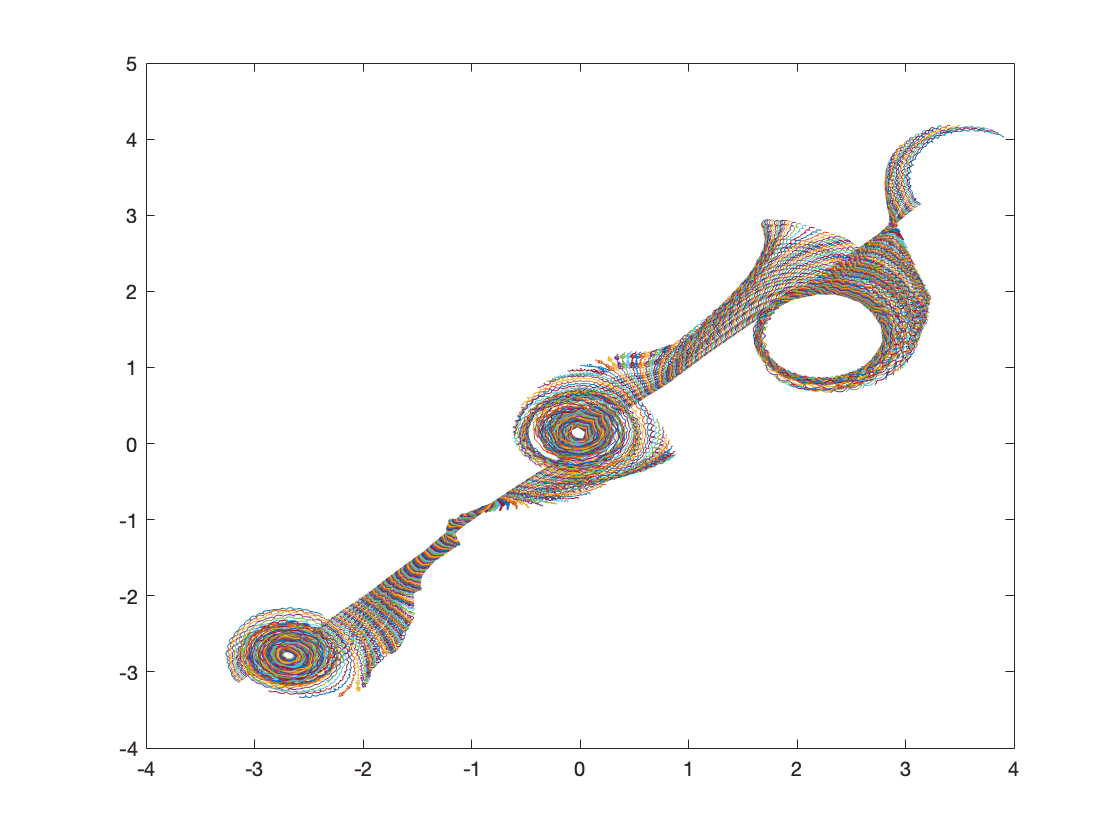

figure,
plot(trajX, trajY)

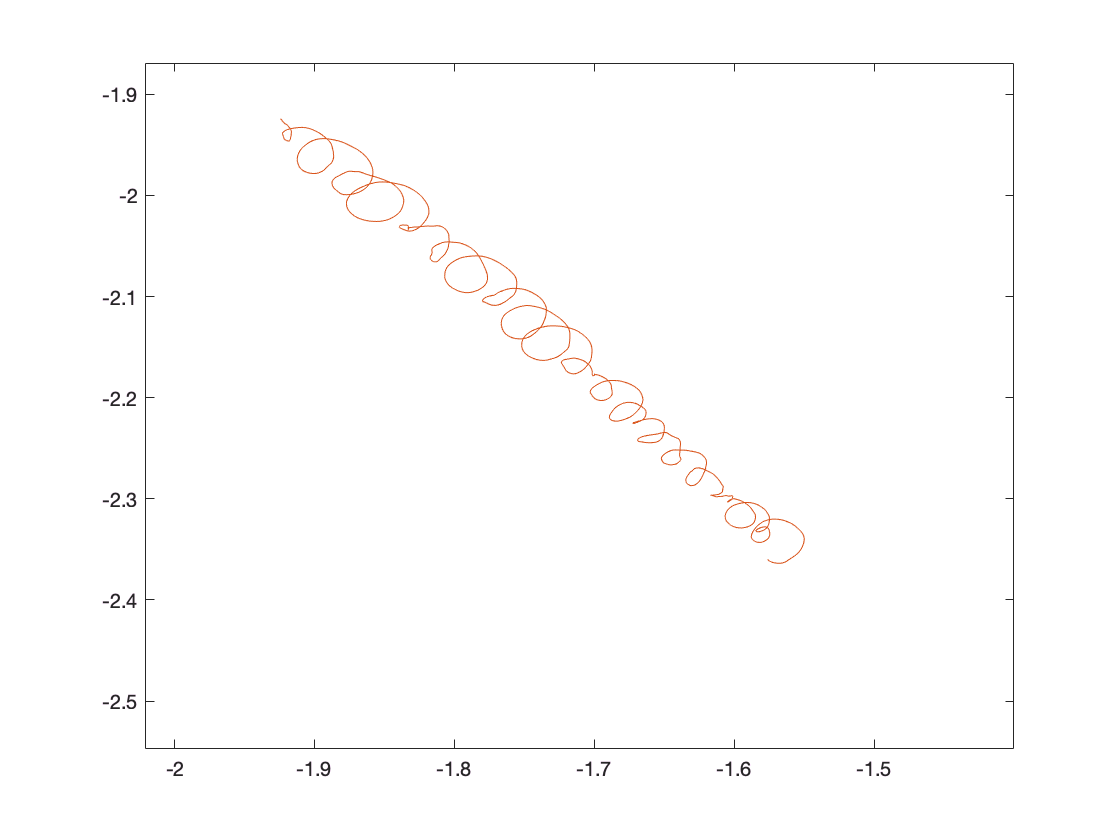

figure,
plot(trajX(:,1), trajY(:,1))
hold all
plot(trajX(:,100), trajY(:,100))

% spectra with noise 
len = length(trajT)-1; 
ntrajs = size(trajX,2);
psi = sleptap(len); 

SLEPTAP calculating tapers of length 512.
SLEPTAP interpolating to length 2500.



CV_mod = zeros(len, ntrajs);

for nseg=1:ntrajs
    u = diff(trajX(:,nseg))./diff(trajT)';
    v = diff(trajY(:,nseg))./diff(trajT)';
    CV_mod(:,nseg) = u + sqrt(-1)*v;
end


[F_mod, SPP_mod, SNN_mod, SPN_mod] = mspec(CV_mod, psi,'cyclic');

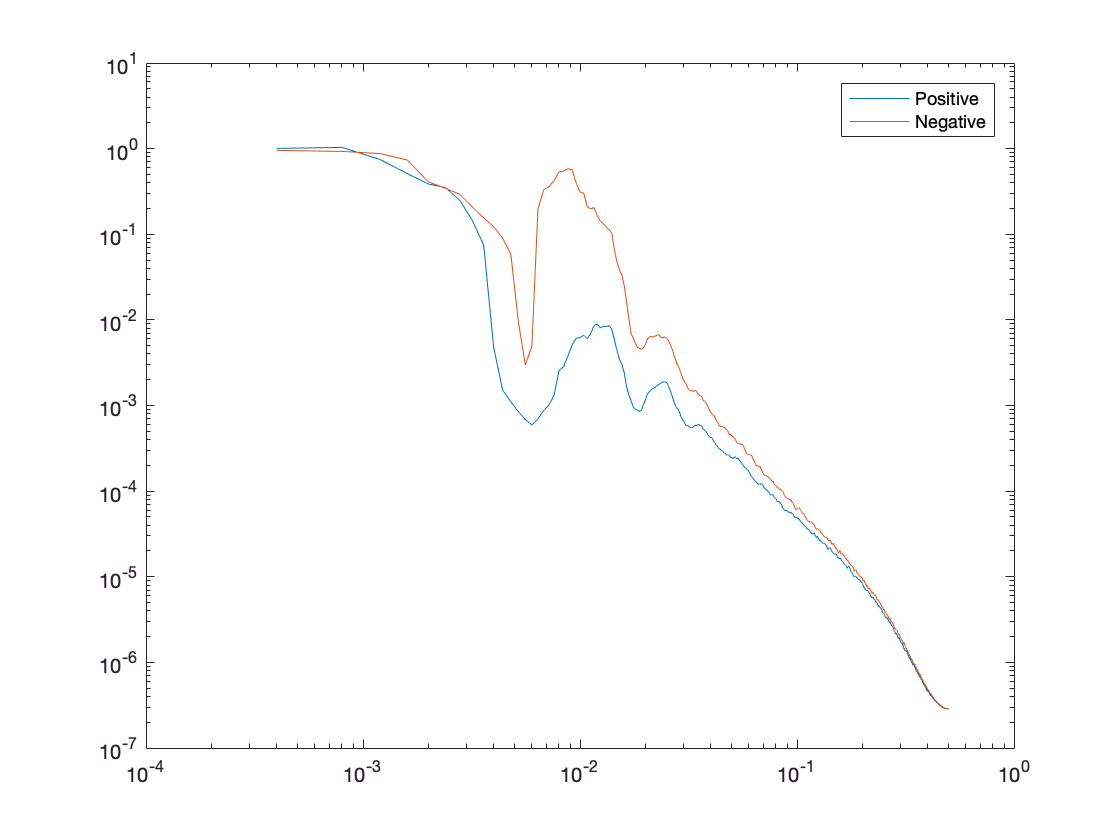

figure,
loglog(F_mod, nanmean(SPP_mod,2))
hold all
loglog(F_mod, nanmean(SNN_mod,2))
legend('Positive','Negative')

%% first define the distance axis 
gamma = 1.2;
dist_bin(1) = pi/1024; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>2*pi,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

% structure function with noise

traj.X = trajX(1:end-1,:);
traj.Y = trajY(1:end-1,:); 
traj.U = real(CV_mod); 
traj.V = imag(CV_mod);

distance = [0.016, 0.02];
sep_mod = idealmodel_sep_cals(traj, distance);

S2ll_mod  = S2ll_model(sep_mod.sep, dist_bin);

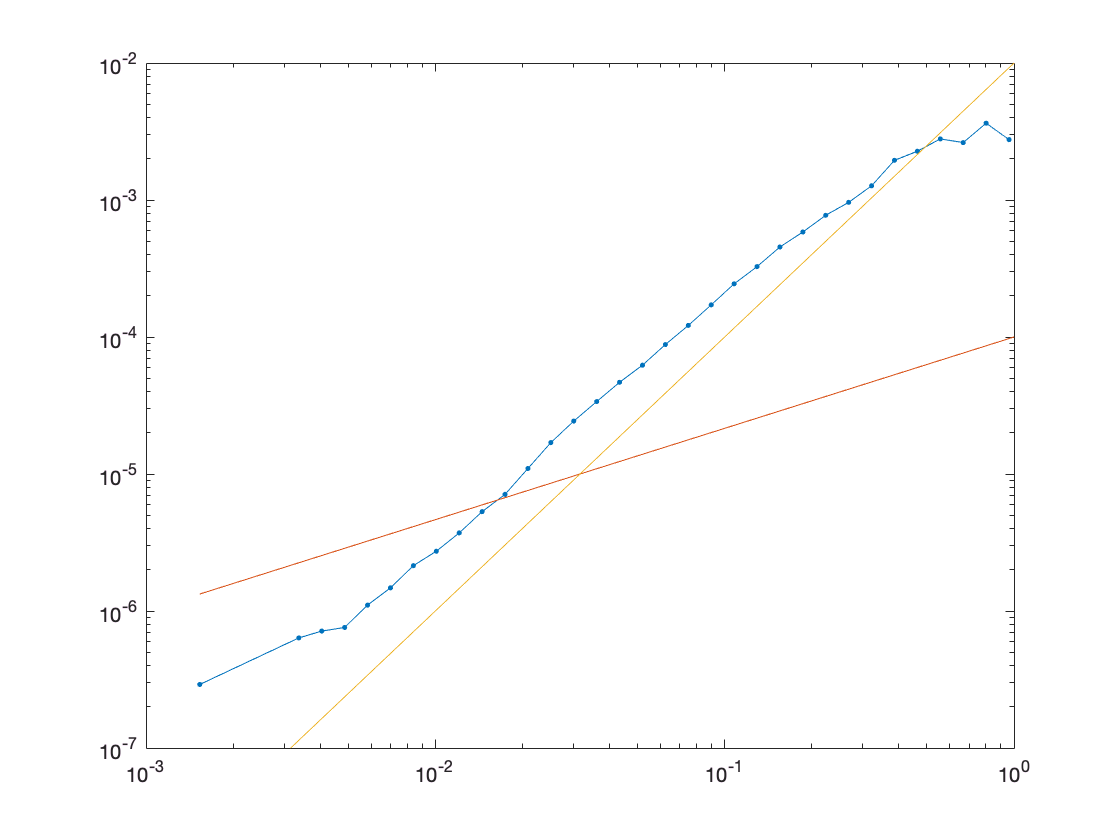

figure
loglog(dist_axis, S2ll_mod,'.-')
hold all 
loglog(dist_axis, 1e-4*dist_axis.^(2/3))
loglog(dist_axis, 1e-2*dist_axis.^(2))
axis([1e-3, 1, 1e-7, 1e-2])

legend('SW Particles', 'r^{2/3}', 'r^2')

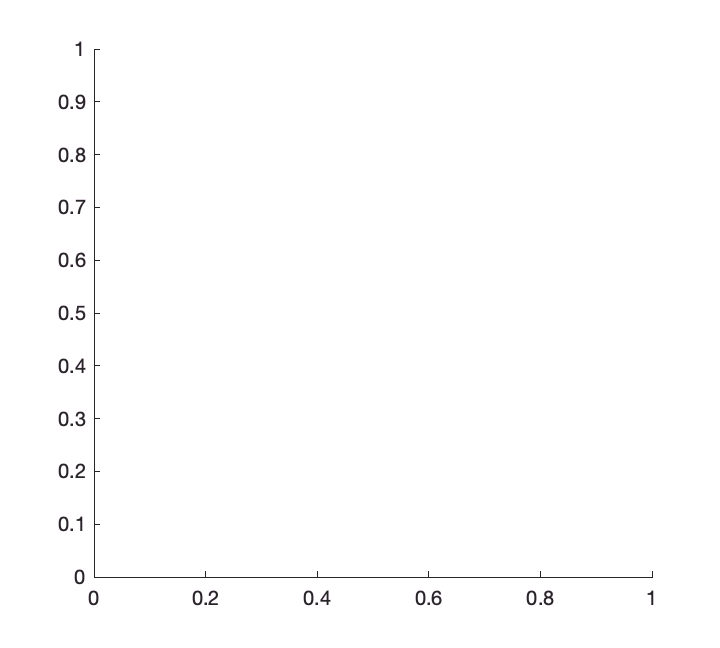

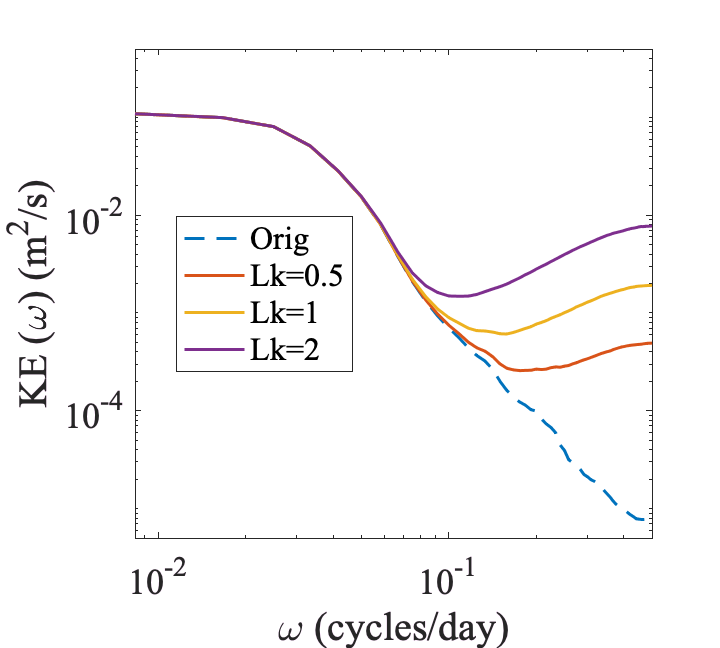

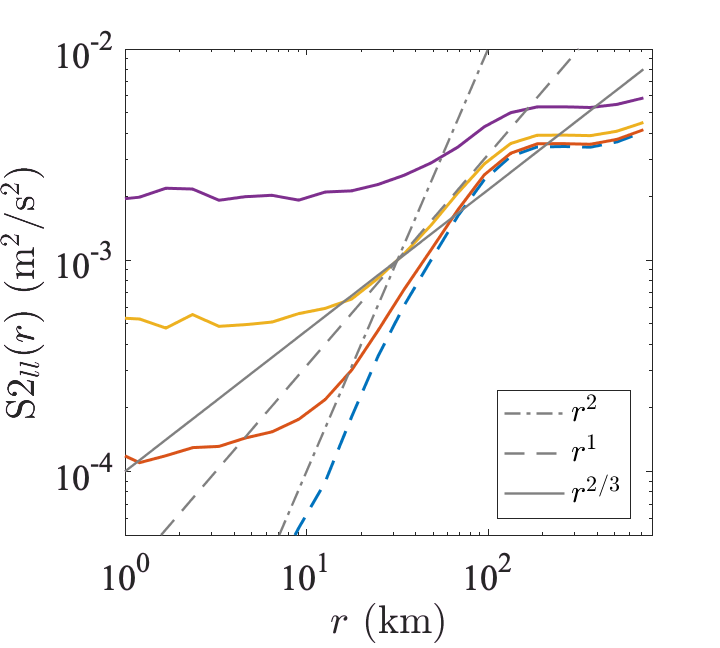

colors = get(gca,'Colororder');

% check dispersion 
ndays=100; 
Mod_disp = rel_disp(sep_mod.sep, ndays);
Mod_noise1_disp = rel_disp(sep_mod_noise1.sep, ndays);
Mod_noise2_disp = rel_disp(sep_mod_noise2.sep, ndays);
Mod_noise3_disp = rel_disp(sep_mod_noise3.sep, ndays);

Moddisp = Mod_disp.avdisp/1e6; 
Modnoise1disp = Mod_noise1_disp.avdisp/1e6; 
Modnoise2disp = Mod_noise2_disp.avdisp/1e6; 
Modnoise3disp = Mod_noise3_disp.avdisp/1e6; 

T = 0:99;

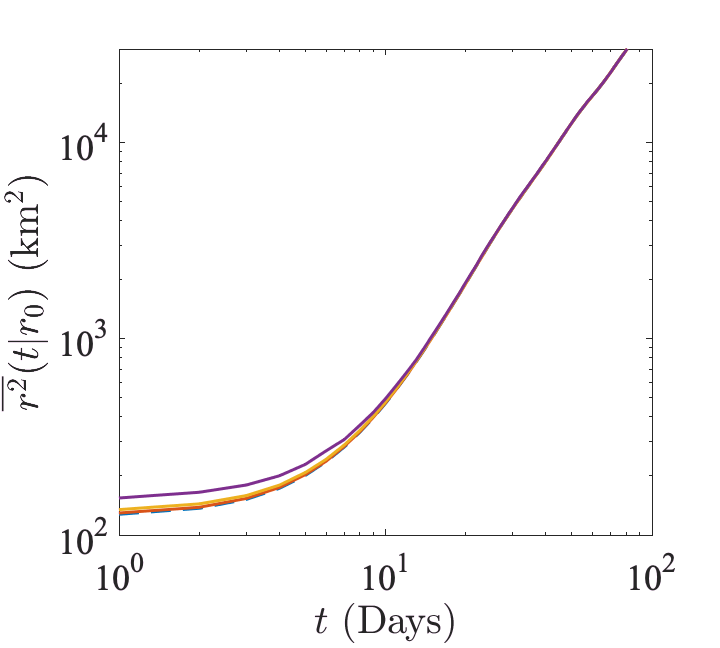

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
j=1;

g(i) = loglog(T+0.001, Moddisp, '--', 'color', colors(1,:), 'linewidth', 1.5);
hold all 
g(i) = loglog(T+0.001, Modnoise1disp, '-', 'color', colors(2,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise2disp, '-', 'color', colors(3,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise3disp, '-', 'color', colors(4,:), 'linewidth', 1.5);    

Tax= T(5:50);
%t3 = loglog(Tax, 10^0.7*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
%t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


%A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([1 100 10^2 3*10^4])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)$ (km$^2$)', 'Interpreter','Latex')
print('noise_disp.eps', '-depsc', '-r400')

% check relative diffusivity

mod_sep_for_sep = model_sep_calcs(mod_traj, [0, 50]*1e3); 
mod_noise1_sep_for_sep = model_sep_calcs(mod_traj_noise(1), [0, 50]*1e3); 
mod_noise2_sep_for_sep = model_sep_calcs(mod_traj_noise(2), [0, 50]*1e3); 
mod_noise3_sep_for_sep = model_sep_calcs(mod_traj_noise(3), [0, 50]*1e3); 

rd1_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,1); 

rd6_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,6); 

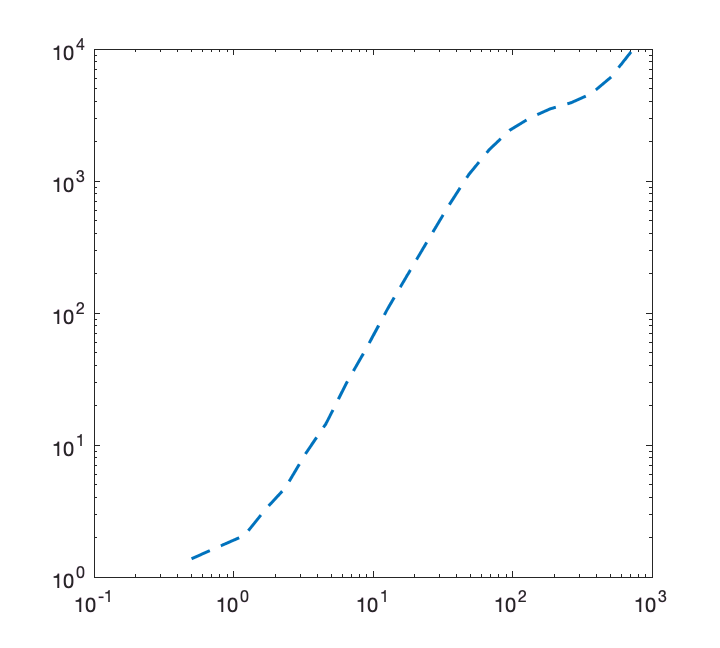

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd6_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all

g(2) = loglog(dist_axis/1e3, rd6_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));

Undefined variable "rd6_mod_noise1" or class "rd6_mod_noise1.rdmean".

g(3) = loglog(dist_axis/1e3, rd6_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd6_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff6.eps', '-depsc', '-r400')

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd1_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd1_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd1_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd1_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


%A = legend([r2, r43], ...
%    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
%    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff.eps', '-depsc', '-r400')

% Check FSLE
flag_1time= 1;
fsle_mod = fsle_model(sep_mod.sep, dist_bin, 1, flag_1time); 

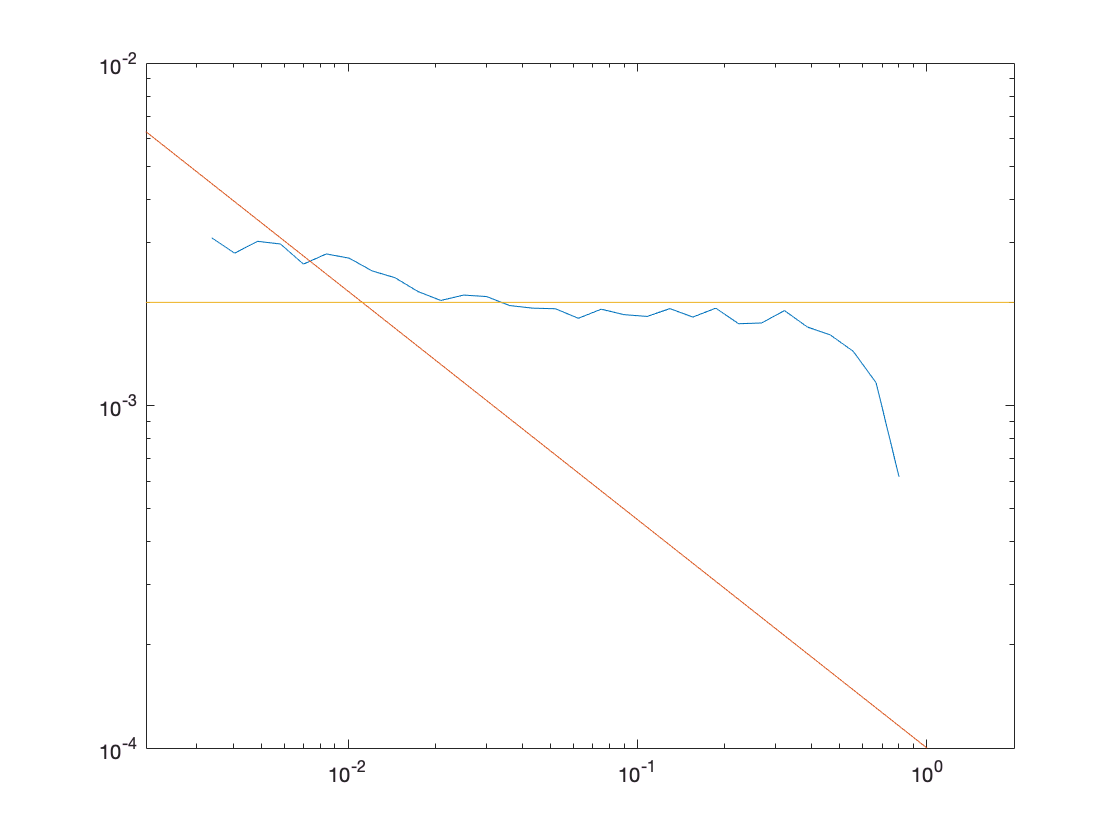

figure,
loglog(dist_axis, fsle_mod)
hold all
loglog(dist_axis, 1e-4*dist_axis.^(-2/3))
loglog(dist_axis, 2e-3*dist_axis.^(0))
axis([2e-3, 2, 1e-4, 1e-2])

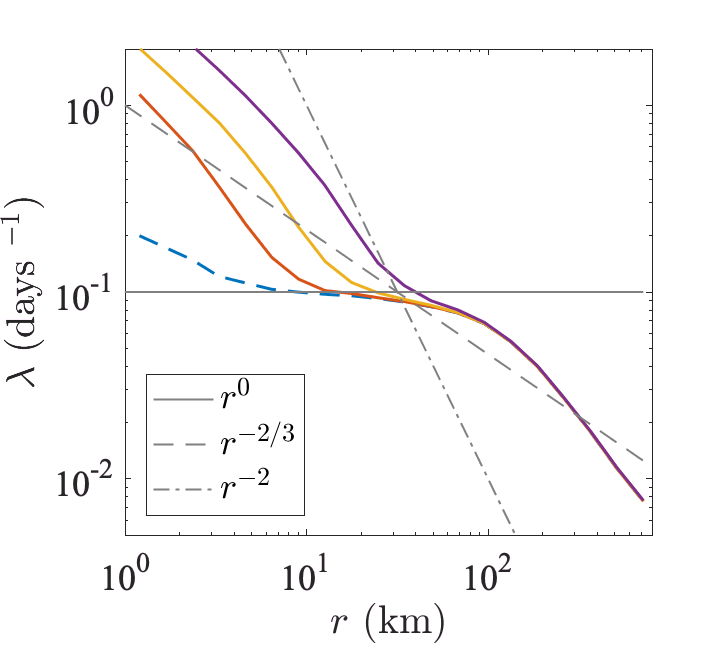

%% Figure for deep
close all 
clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')

        
%g(1) = loglog(dist_axis/1e3, fsle_mod_deep, '--', 'linewidth',2,'color', colors(2,:));
g(1) = loglog(dist_axis/1e3, fsle_mod, '--', 'linewidth',1.5, 'color', colors(1,:)); 
hold all 
g(2) = loglog(dist_axis/1e3, fsle_mod_noise1, '-', 'linewidth',1.5, 'color', colors(2,:)); 
g(3) = loglog(dist_axis/1e3, fsle_mod_noise2, '-', 'linewidth',1.5, 'color', colors(3,:)); 
g(4) = loglog(dist_axis/1e3, fsle_mod_noise3, '-', 'linewidth',1.5, 'color', colors(4,:)); 

r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 


A = legend([ r0, r23, r2], ...
    {'$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',18);
%legend boxoff
%set(A, 'location','best') 
set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 50*1e-4 2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')
print('noise_FSLE.eps', '-depsc', '-r400')